Now we have plotted the tuning curves for all cells in our population. Let's use some statistical measures to characterize the properties of the neurons in our population.

Using the AveON and AveOFF matrices, we will measure two properties for each neuron: its **preferred orientation **and its **orientation selectivity index (OSI)**.

load('TC.mat');       

NumOrientations = 12;

Before calculating these two properties, we need to remove all ON responses that were weaker than the average OFF response. To do this, we will subtract `OFF_mean` from the `ON_mean` matrix.

To replicate the 1D `OFF_mean` vector across NumOrientations columns so that the subtraction can be done, the `repmat` function is used.

OFF_mean = repmat(OFF_mean,1,NumOrientations); 
TC = ON_mean - OFF_mean;

After subtracting the two matrices and storing the tuning curve in `TC`, remove all negative values using logical indexing, and replace them with zeroes.

TC(TC<0) = 0;

Write a `for` loop that calculates the PO and OSI for each neuron, , and stores the values for each property into a separate vector (`AllPO` and `AllOSI` respectively).

NumCells = size(TC,1);
Orientations = 0:30:330;
AngRad = Orientations*pi/180;        

% initialize your vectors        
AllOSI = zeros(1,NumCells);
AllPO = zeros(1,NumCells);
        
for cell = 1:NumCells
    
    TC_cell = TC(cell,:);

    OSI = abs(sum(TC_cell.*exp(2.*1i.*AngRad))./sum(TC_cell));
    
    PrefOri = 0.5.*(angle(sum(TC_cell.*exp(2.*1i.*AngRad))));
    PO = PrefOri.*(180/pi);
    if PO<0
        PO = PO + 180;
    end
       
    AllOSI(cell) = OSI;
    AllPO(cell) = PO;    
        
end

Plot two histograms: one for Preferred Orientation and one for OSI.

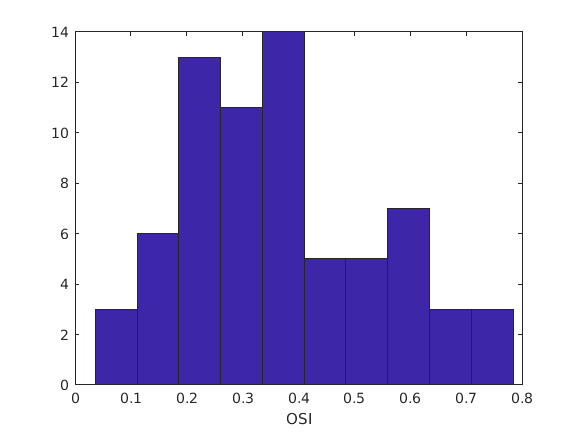

figure()       
hist(AllOSI)      
xlabel('OSI')        

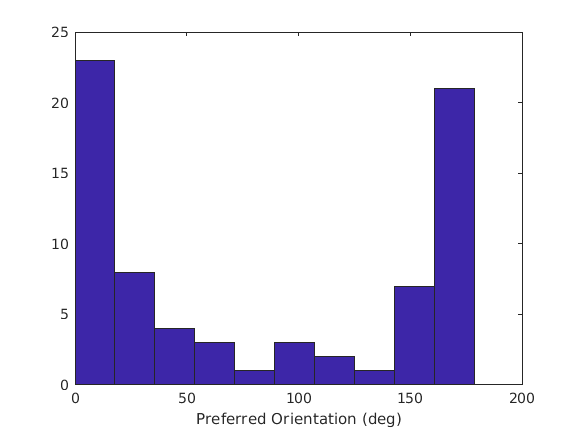

figure()
hist(AllPO)  
xlabel('Preferred Orientation (deg)')